**Multiobjective Problem. Scalarization Method**


$$\left\lbrace \begin{array}{ll}
\mathrm{minimize} & \left(x_1 -x_2 \right),\left(x_1 +x_2 \right)\\
\mathrm{subject}\;\mathrm{to} & -2x_1 +x_2 \le 0\\
\; & -x_1 -x_2 \le 0\\
\; & 5x_1 -x_2 \le 6
\end{array}\right.$$


Find the set of minima and weak minima by means of the scalarization method

close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

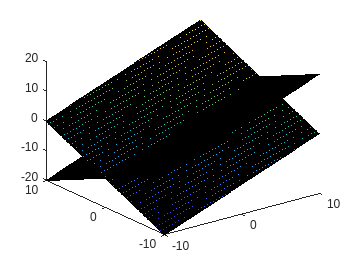

% Plot Graph

x1 = -10:0.1:10;
x2 = -10:0.1:10;

[X1,X2] = meshgrid(x1,x2);

X3 = X1-X2;
X4 = X1+X2;

surface(X1,X2,X3);
hold on
surface(X1,X2,X4);
view(3)
hold off

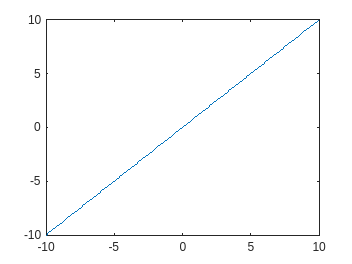

% 2D plot X1
x1 = x2;
plot(x1,x2);

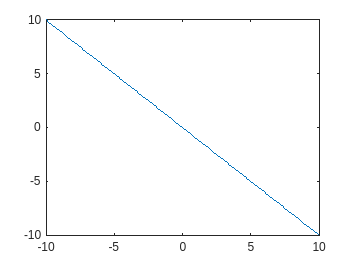

% 2D plot X2
x2 = -x1;
plot(x1,x2);

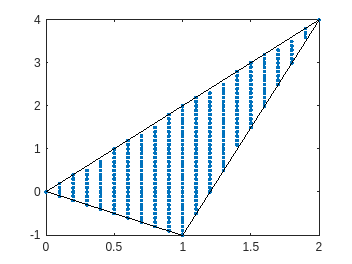

% Feasible Area
x1 = -10:0.1:10;
x2 = -10:0.1:10;

[X1, X2] = meshgrid(x1,x2);

condition_x1 = X1((X2 <= 2*X1) & (-X1 - X2 <= 0) & (5*X1 - X2 <= 6));
condition_x2 = X2((X2 <= 2*X1) & (-X1 - X2 <= 0) & (5*X1 - X2 <= 6));

plot(condition_x1, condition_x2, '.');
hold on
plot([0 2],[0 4],'-k');
plot([2 1],[4 -1],'-k');
plot([1 0],[-1 0],'-k');

% Linear Multiobjective problem. Scalarization Method

C = [1 -1
     1  1];

A = [-2  1
     -1 -1
      5 -1];

b = [0
     0
     6];

% Calculate different Alpha
options = optimset('Display', 'off');
for alpha = 0.001:0.001:0.999
    f = [1
         1-2*alpha];
  
    x = linprog(f,A,b, [], [], [],[], options);
    plot(x(1),x(2), 'r.');
end

fprintf('Alpha 0 \n');

Alpha 0 


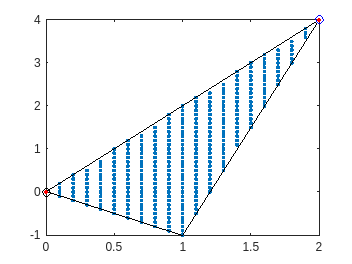

alpha = 0;
f = [1
     1-2*alpha];

x0 = linprog(f,A,b, [], [], [],[], options);
plot(x0(1), x0(2), 'ko');


alpha = 1;

f = [1
    1-2*alpha];

x1 = linprog(f,A,b, [], [], [], [], options);
plot(x1(1), x1(2), 'bo');
hold off